# Support Vector Machines Machines: Exercises, II

## Boris Shilov

In this exercise I will attempt to look into the least squares support vector machine formulations using the LS-SVM Matlab toolbox, particularly functon estimation and time series prediction. Unlike normal SVM, LS-SVM is intended to fit a numerical predictive function to the data.

Unlike linear regression, LS-SVM uses only a subset of points to decide the optimal hyperplane. These are the points corresponding to the support vectors, that are outside the $\epsilon$ tube, and changing which would change the optimal hyperplane. By contrast, changing any data point within a training set used for a linear regression classifier would change the classifier.

rng('default')
rng(333)

### sinc regression

We can construct an example dataset using a noisy sinc function. Sinc is thus the true data generating process, and the task of an LS-SVM classifier will be to approximate this function without overfitting to replicate the noise.

X = transpose(-3:0.01:3);
Y = sinc(X) + 0.1 * randn(length(X), 1);
Xtrain = X(1:2: end); Ytrain = Y(1:2: end);
Xtest = X(2:2: end); Ytest = Y(2:2: end);

We can attempt approximation using the RBF kernel, iterating over a small parameter space.

gams = [10, 10e3, 10e6]; sigmas = [0.01, 1, 100];
[sigmasMesh, gamsMesh] = meshgrid(sigmas, gams);
parameterSpace = num2cell([gamsMesh(:), sigmasMesh(:)], 2);

perfList = cellfun(@(cell) crossvalidate({ Xtrain , Ytrain , 'f', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, 10, 'mse'), parameterSpace)

perfList =     0.0125
    0.0140
    0.0172
    0.0381
    0.0113
    0.0111
    0.1376
    0.1162
    0.0895


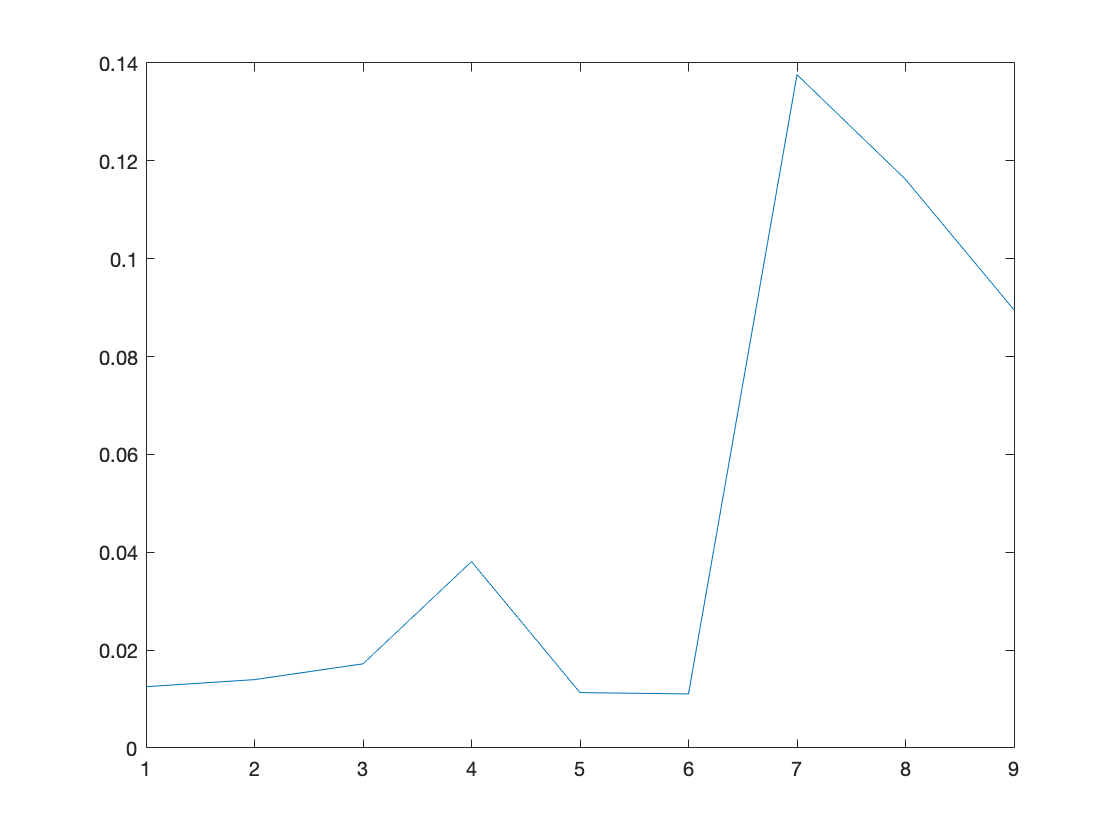

plot(perfList)

It seems that the fifth and sixth models are the best fitting on training set. Their parameters are:

parameterSpace{5} 

ans =        10000           1


parameterSpace{6}

ans =     10000000           1


We can choose between them, as well as the first two models which are relatively well fitting, using the AUC of test set performance.

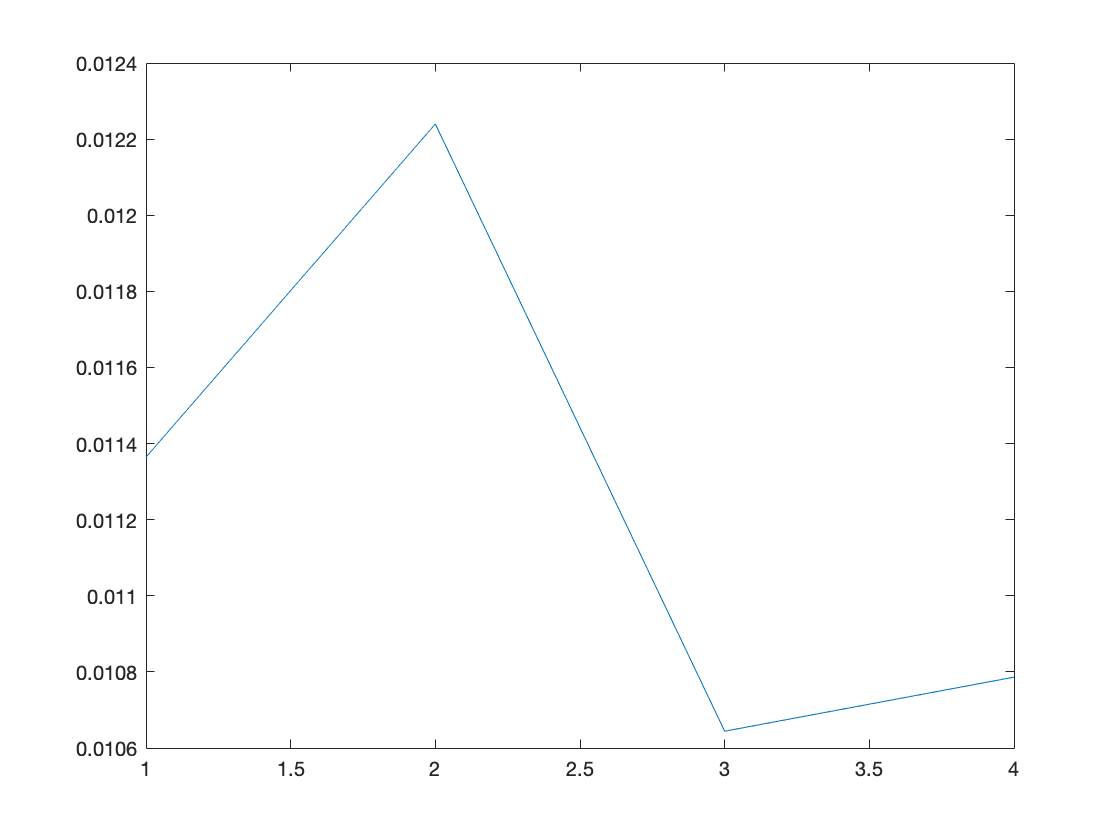

niceParams = cellfun(@(index) parameterSpace{index}, {1 2 5 6}, 'UniformOutput', false);
niceModelSpecs = cellfun(@(cell) { Xtrain , Ytrain , 'f', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, niceParams, 'UniformOutput', false);
niceModels = cellfun(@(cell) trainlssvm(cell), niceModelSpecs, 'UniformOutput', false);
niceSpecAndModel = cellfun(@(index) {niceModelSpecs{index}, ...
    niceModels{index}}, {1 2 3 4}, 'UniformOutput', false);
[Yest, Zt] = cellfun(@(cell) simlssvm(cell{1}, ...
    {cell{2}.alpha, cell{2}.b}, Xtest), niceSpecAndModel, 'UniformOutput', false);
test_mses = cellfun(@(cell) immse(cell, Ytest), Yest);
plot(test_mses)

It seems the fifth model fits the best on the test case. We may visualise the fifth model on the test data points.

modelSpec= {Xtrain, Ytrain, 'f', parameterSpace{5}(1), parameterSpace{5}(2), 'RBF_kernel'};
model = trainlssvm(modelSpec);
Yest = simlssvm(modelSpec, {model.alpha, model.b}, Xtest)

Yest =    -0.0855
   -0.0777
   -0.0695
   -0.0609
   -0.0521
   -0.0430
   -0.0338
   -0.0245
   -0.0151
   -0.0058


figure;
plotlssvm(modelSpec, {model.alpha, model.b});

Start Plotting...

finished


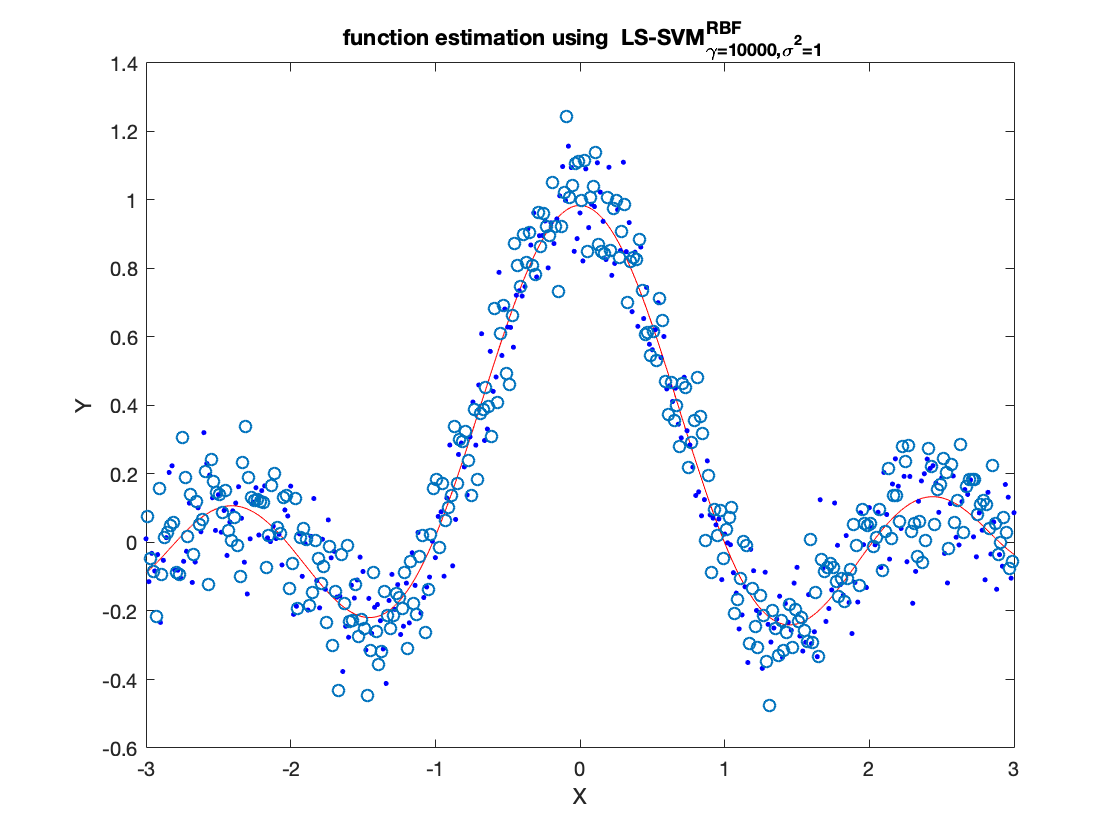

hold on;
scatter(Xtest, Ytest)
hold off;

Since the RBF kernel function estimation SVM is quite flexible, there should exist a pair of parameters that are optimal in the sense that, given these parameters, the resulting SVM is the best approximation of the underlying data-generating function possible. However, as we typically do not have direct access to the data generating process, a broader optimality criterion for parameters is that the resulting SVM is the best performing on some test set among the set of all possible SVMs. Some exceptions to this are possible - for example, there may be multiple near equal maxima or minima in the parameter space. This would correspond to having two or more models that fit the data equally well.

We can compare the resulting model to automatic parameter tuning.

[gamSimp, sigSimp, costSimp] = tunelssvm({Xtrain, Ytrain, 'f', ...
    [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10, 'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         14.9105
                                          [sig2]        0.30308
                                          F(X)=         0.011061
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   14.9105     0.303075

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.106100e-02     2.7021        -1.1938      initial 
     2           5     1.106100e-02     2.7021        -1.1938      contract outside 
     3           7     1.106100e-02     2.7021        -1.1938      contract inside 
     4           9     1.106100e-02     2.7021   

[gamGrid, sigGrid, costGrid] = tunelssvm({Xtrain, Ytrain, 'f', ...
    [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm', {10, 'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7129.7485
                                          [sig2]        0.79574
                                          F(X)=         0.010974
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   354.9693    0.06531841
    cost of starting values:           0.011754
    time needed for 1 evaluation (sec):0.06
    limits of the grid:   [gam]         354.969276      1058148.4984
                          [sig2]        0.065318      9.6941
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=9.872    -0.22848 ,F(X)=0.010955;
ITERATION: 2
  dF=4.9462e-07, dX=0.45169, X=9.4231     -0.2779 ,F(X)=0.010954;
Obtained hyper-parameters: [gamma sig2]: 12370.3438     0.757372403


It appears that we have by chance stumbled upon a slightly better model than determined by these parameters, since the test MSE of our fifth model is better than even the train MSEs found by automated tuning. Both methods produce similar results. Doing more iterations in both algorithms, over a larger space, could probably tune into the value we have found.

### Bayesian tuning